clc;
clear all;
warning off;
addpath(genpath(pwd));
%     A1     b1      A2      b2      A5      b5      Tp      Tf     Tvl
%     Tv0    yita    S1      S2      S3      S4      k0      k1     k2      k3
lb = [
      0       %A1
      0       %b1
      0       %A2
      0       %b2
      0       %Tp
      0       %Tf0
      0       %Tvl
      0       %Tv0
      0.85    %yita
     ]; 

ub = [
      0.8     %A1
      0.8     %b1
      0.8     %A2
      0.8     %b2
      10       %Tp
      5       %Tf0
      15      %Tvl
      5      %Tv0
      0.95    %yita
     ];    

Npara = length(lb); 

A1   = 0.3         ; A2   = 0.3        ;
b1   = 0.3        ; b2   = 0.3           ;
Tp   = 5           ; Tf0  = 1             ;
Tvl  = 8            ; Tv0  = 2             ;
st   = 0.19          ; yita = 0.95          ;

para_init = [A1,b1,A2,b2,...
            Tp,Tf0,Tvl,Tv0,...
            yita];

%% ==================== 1. Operating condition setup ============================
meanangle    = -9.4;
averageangle = 7;
conditions   = input_condition(meanangle,averageangle);
airfoildata  = input_afdata;

CFDdatapath = resolve_data_file('re5e5_i9.4_f2.4.txt', 'cfd');

%% ==================== 2. Collect variables ============================
setcase.meanangle    = meanangle;
setcase.averageangle = averageangle;
setcase.conditions   = conditions;
setcase.airfoldata   = airfoildata;
setcase.CFDdatapath  = CFDdatapath;

para_local_DTW = run_optimal_DTW(para_init,Npara,lb,ub,setcase);

===== Starting dynamic-stall BL parameter optimization [CFD fit + area similarity] =====

single objectiveoptimization:
9 variable
1 nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675       3.58223            0      0
    2          25094       3.57203            0      0
    3          37513       3.57161            0      0
optimizationend: average change in fitness value is less than options.FunctionTolerance and constraint violation is less than options.ConstraintTolerance。
===== optimization completed！best fitness value = 3.57161272 =====

==================== Initial vs Optimized Parameter Comparison ====================
initial fitness=36.538046 | optimized fitness=3.571613
   A1 : initial v

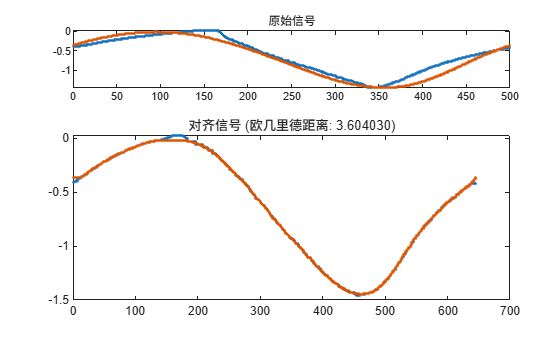

ans = 3.6040

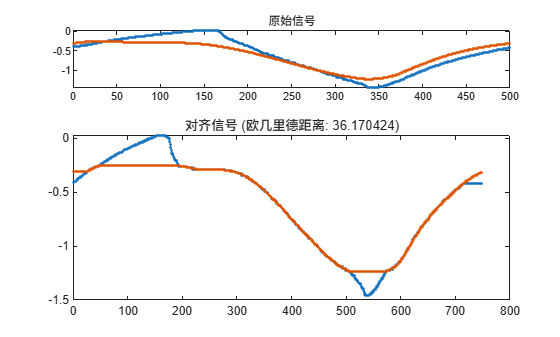

ans = 36.1704

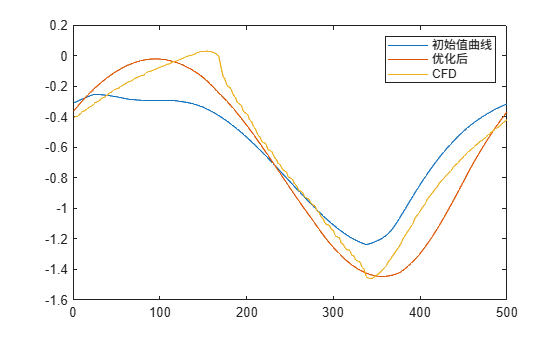

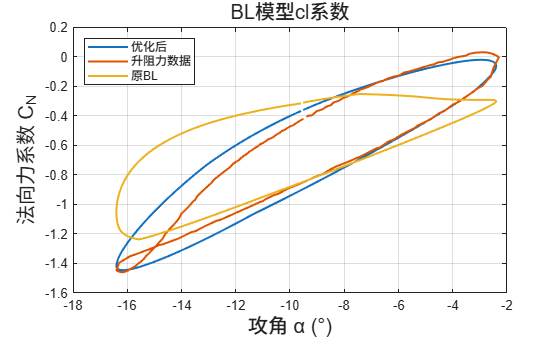

compare_optimal_result_DTW(para_local_DTW,para_init,setcase);

para_local_ARE = run_optimal_ARE(para_init,Npara,lb,ub,setcase);

===== Starting dynamic-stall BL parameter optimization [CFD fit + area similarity] =====

single objectiveoptimization:
9 variable
1 nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675      0.185182            0      0
    2          25094      0.185115            0      0
    3          37513      0.185109            0      0
optimizationend: average change in fitness value is less than options.FunctionTolerance and constraint violation is less than options.ConstraintTolerance。
===== optimization completed！best fitness value = 0.18510854 =====

==================== Initial vs Optimized Parameter Comparison ====================
initial fitness=0.339114 | optimized fitness=0.185109
   A1 : initial va

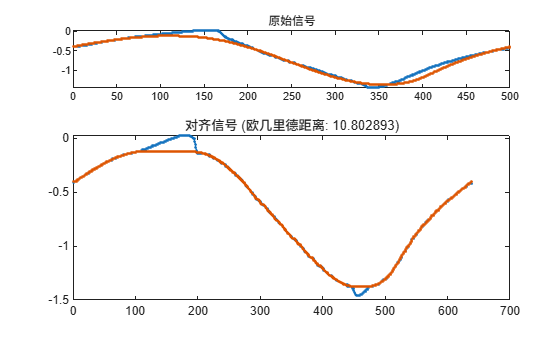

ans = 10.8029

ans = 36.1704

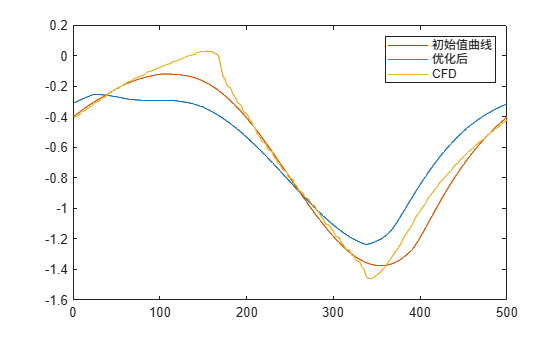

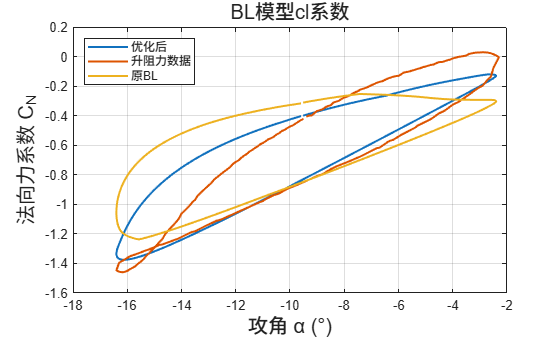

compare_optimal_result_ARE(para_local_ARE,para_init,setcase);

para_local_MSE = run_optimal_MSE(para_init,Npara,lb,ub,setcase);

===== Starting dynamic-stall BL parameter optimization [CFD fit + area similarity] =====

single objectiveoptimization:
9 variable
1 nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675      0.521286            0      0
    2          25094      0.517944            0      0
    3          37513      0.517892            0      0
optimizationend: average change in fitness value is less than options.FunctionTolerance and constraint violation is less than options.ConstraintTolerance。
===== optimization completed！best fitness value = 0.51789188 =====

==================== Initial vs Optimized Parameter Comparison ====================
initial fitness=3.163103 | optimized fitness=0.517892
   A1 : initial va

compare_optimal_result_MSE(para_local_MSE,para_init,setcase);

ans = 12.5340

ans = 36.1704

para_local_GZ = run_optimal_GZ(para_init,Npara,lb,ub,setcase);

===== Starting dynamic-stall BL parameter optimization [CFD fit + area similarity] =====

single objectiveoptimization:
9 variable
1 nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675       1.00839            0      0
    2          25094       1.00563            0      0
    3          37513       1.00462            0      0
optimizationend: average change in fitness value is less than options.FunctionTolerance and constraint violation is less than options.ConstraintTolerance。
===== optimization completed！best fitness value = 1.00462045 =====

==================== Initial vs Optimized Parameter Comparison ====================
initial fitness=0.339114 | optimized fitness=0.291577
   A1 : initial va

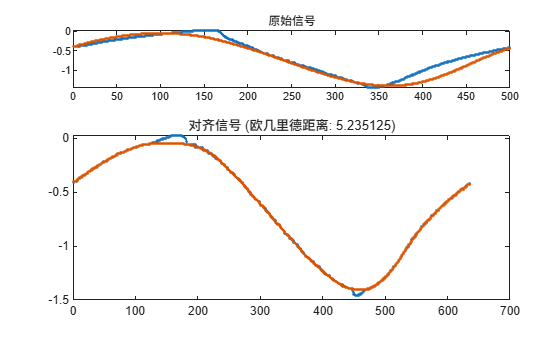

ans = 5.2351

ans = 36.1704

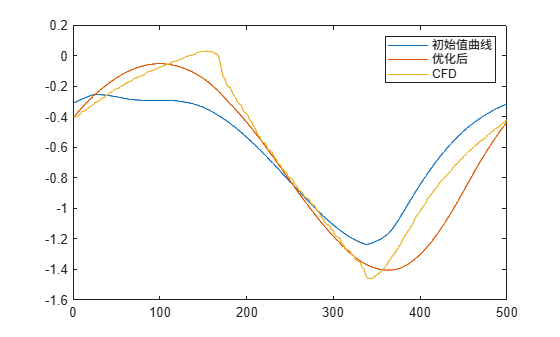

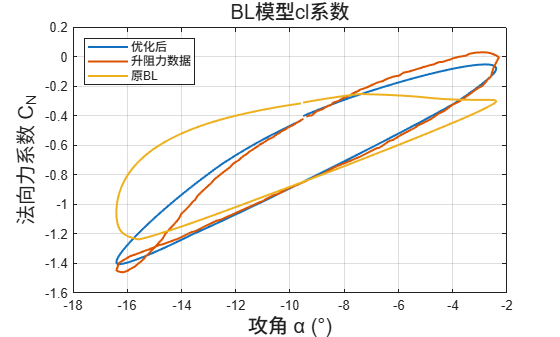

compare_optimal_result_GZ(para_local_GZ,para_init,setcase);

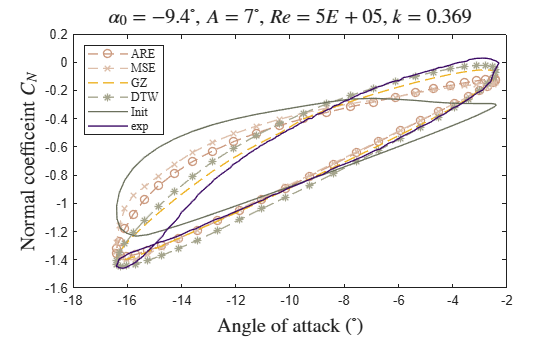

load("data_collection_ARE.mat")
ARE_data = [ARE_data(1:10:end,:)
            ARE_data(1,:)];
load("data_collection_DTW.mat");
DTW_data = [DTW_data(1:10:end,:)
            DTW_data(1,:)];
load("data_collection_GZ.mat");
GZ_data = [GZ_data(1:10:end,:)
            GZ_data(1,:)];
load("data_collection_MSE.mat");
MSE_data = [MSE_data(1:10:end,:)
            MSE_data(1,:)];

init_data = [init_data(1:10:end,:)
             init_data(1,:)];

exp_data = [exp_data
            exp_data(1,:)];

figure
fontsize = 15;
line = 1;
% plot(ARE_data(:,1) ,ARE_data(:,2) ,'o--','LineWidth',line,'Color',[237/255 179/255 39/255])
% hold on
% plot(DTW_data(:,1) ,DTW_data(:,2) ,'*--','LineWidth',line,'Color',[243/255 126/255 120/255])
% plot(MSE_data(:,1) ,MSE_data(:,2) ,'x--','LineWidth',line,'Color',[65/255  137/255 200/255])
% plot(init_data(:,1),init_data(:,2),      'LineWidth',line,'Color',[141/255 90/255  133/255])
% plot(exp_data(:,1) ,exp_data(:,2) ,      'LineWidth',line,'Color',[58/255  9/255   100/255])

plot(ARE_data(:,1) ,ARE_data(:,2) ,'o--','LineWidth',line,'Color',[203/255 153/255 126/255])
hold on
plot(MSE_data(:,1) ,MSE_data(:,2) ,'x--','LineWidth',line,'Color',[221/255 190/255 169/255])
plot(GZ_data(:,1) ,GZ_data(:,2) ,'--','LineWidth',line)
plot(DTW_data(:,1) ,DTW_data(:,2) ,'*--','LineWidth',line,'Color',[165/255 165/255 141/255])
plot(init_data(:,1),init_data(:,2),      'LineWidth',line,'Color',[107/255 112/255 92/255])
plot(exp_data(:,1) ,exp_data(:,2) ,      'LineWidth',line,'Color',[58/255  9/255   100/255])

legend('ARE','MSE','GZ','DTW',"Init",'exp','Location', 'northwest','FontName', 'Times New Roman');
title(sprintf('$\\alpha_0=%.1f^\\circ$, $A=%d^\\circ$, $Re=%.0E$, $k=%.3f$', meanangle, averageangle,conditions.Re,conditions.k), ...
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize);

xlabel('Angle of attack ($^\circ$)', ... 
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize); 

ylabel('Normal coefficeint $C_N$', ... 
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize);
saveas(gcf, ['opt_compare','.png']);
exportgraphics(gcf,'opt_compare.pdf','ContentType', 'vector')